# Synthesize a controller with a setteling time of 2 min. 

clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);
%Wref
%lowpass filter wich result in a setling time of 10 min (600 sec) .  
s=tf('s');
wref =eye(4)*(1/(120*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;
%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);

## FWMM on SF

param.model.Dwz = 5*eye(4);
param = control.DesignProcedureFWMM(param,0);

Evaluation of design procedure for FWMM 
Gamma is found to be: 0.589177 


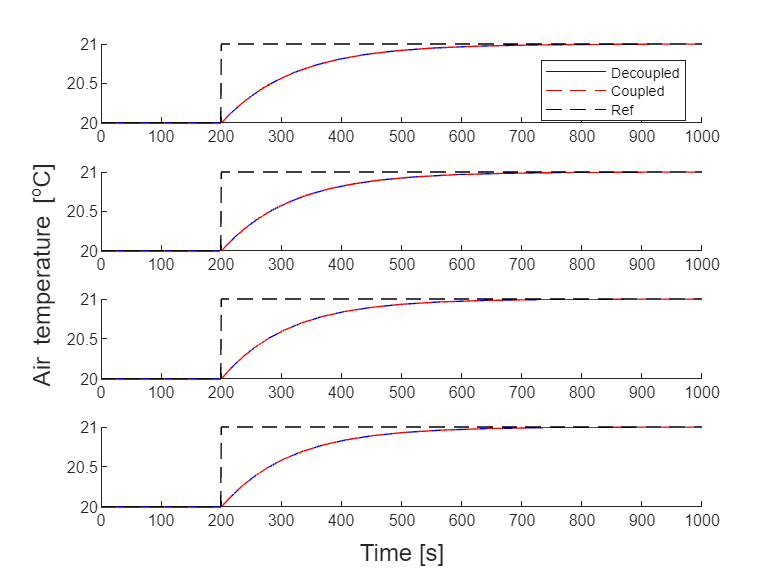

[resDeSF,resSF] = util.SimulateStep(param,"SimulateNonlinearStatefeedbackResults",0,1000);

info = stepinfo(resSF.Ta(:,1),resSF.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SF is: %f \n', (info.SettlingTime - 200));

Settling time for SF is: 593.680626 


## FWMM on SOF

param.model.Dwz = 6.5*eye(4); %6 prev  / 5,5=644
param = control.DesignProcedureSOF_ILMI_FWMM(param,0,{[-1,1]});

ans = 32.6612

ans = 1.4795

ans = 0.5609

ans = 0.2599

ans = 0.1571

ans = 0.1259

ans = 0.1131

ans = 0.1063

ans = 0.1023

ans = 0.0998

ans = 0.0981

ans = 0.0969

ans = 0.0960

ans = 0.0953

ans = 0.0947

ans = 0.0942

ans = 0.0938

ans = 0.0934

ans = 0.0931

ans = 0.0928

ans = 0.0926

ans = 0.0923

ans = 0.0921

ans = 0.0919

ans = 0.0918

ans = 0.0916

ans = 0.0914

ans = 0.0913

ans = 0.0911

ans = 0.0910

ans = 0.0909

ans = 0.0907

ans = 0.0906

ans = 0.0905

ans = 0.0903

ans = 0.0902

ans = 0.0901

ans = 0.0900

ans = 0.0899

ans = 0.0898

ans = 0.0897

ans = 0.0896

ans = 0.0895

ans = 0.0894

ans = 0.0893

ans = 0.0892

ans = 0.0890

ans = 0.0889

ans = 0.0888

ans = 0.0887

ans = 0.0886

ans = 0.0885

ans = 0.0883

ans = 0.0882

ans = 0.0881

ans = 0.0879

ans = 0.0878

ans = 0.0876

ans = 0.0875

ans = 0.0873

ans = 0.0871

ans = 0.0870

ans = 0.0868

ans = 0.0866

ans = 0.0864

ans = 0.0862

ans = 0.0860

ans = 0.0858

ans = 0.0856

ans = 0.0853

ans = 0.0851

ans = 0.0848

ans = 0.0846

ans = 0.0843

ans = 0.0840

ans = 0.0837

ans = 0.0834

ans = 0.0831

ans = 0.0828

ans = 0.0825

ans = 0.0821

ans = 0.0817

ans = 0.0814

ans = 0.0810

ans = 0.0806

ans = 0.0802

ans = 0.0798

ans = 0.0793

ans = 0.0789

ans = 0.0784

ans = 0.0780

ans = 0.0775

ans = 0.0770

ans = 0.0765

ans = 0.0760

ans = 0.0755

ans = 0.0750

ans = 0.0745

ans = 0.0739

ans = 0.0733

ans = 0.0728

ans = 0.0722

ans = 0.0716

ans = 0.0710

ans = 0.0704

ans = 0.0698

ans = 0.0692

ans = 0.0686

ans = 0.0679

ans = 0.0673

ans = 0.0667

ans = 0.0660

ans = 0.0654

ans = 0.0648

ans = 0.0641

ans = 0.0635

ans = 0.0629

ans = 0.0623

ans = 0.0617

ans = 0.0611

ans = 0.0605

ans = 0.0599

ans = 0.0594

ans = 0.0589

ans = 0.0584

ans = 0.0579

ans = 0.0574

ans = 0.0570

ans = 0.0566

ans = 0.0562

ans = 0.0558

ans = 0.0555

ans = 0.0552

ans = 0.0549

ans = 0.0546

ans = 0.0543

ans = 0.0540

ans = 0.0538

ans = 0.0535

ans = 0.0533

ans = 0.0531

ans = 0.0528

ans = 0.0526

ans = 0.0524

ans = 0.0522

ans = 0.0520

ans = 0.0519

ans = 0.0517

ans = 0.0515

ans = 0.0513

ans = 0.0511

ans = 0.0509

ans = 0.0508

ans = 0.0506

ans = 0.0504

ans = 0.0502

ans = 0.0500

ans = 0.0499

ans = 0.0497

ans = 0.0495

ans = 0.0493

ans = 0.0492

ans = 0.0490

ans = 0.0488

ans = 0.0487

ans = 0.0485

ans = 0.0483

ans = 0.0482

ans = 0.0480

ans = 0.0479

ans = 0.0477

ans = 0.0475

ans = 0.0474

ans = 0.0472

ans = 0.0471

ans = 0.0469

ans = 0.0468

ans = 0.0467

ans = 0.0465

ans = 0.0464

ans = 0.0462

ans = 0.0461

ans = 0.0460

ans = 0.0458

ans = 0.0457

ans = 0.0456

ans = 0.0454

ans = 0.0453

ans = 0.0452

ans = 0.0450

ans = 0.0449

ans = 0.0448

ans = 0.0447

ans = 0.0445

ans = 0.0444

ans = 0.0443

ans = 0.0442

ans = 0.0441

ans = 0.0439

ans = 0.0438

ans = 0.0437

ans = 0.0436

ans = 0.0434

ans = 0.0433

ans = 0.0432

ans = 0.0431

ans = 0.0430

ans = 0.0429

ans = 0.0428

ans = 0.0426

ans = 0.0425

ans = 0.0424

ans = 0.0423

ans = 0.0422

ans = 0.0421

ans = 0.0420

ans = 0.0419

ans = 0.0418

ans = 0.0417

ans = 0.0416

ans = 0.0415

ans = 0.0414

ans = 0.0413

ans = 0.0412

ans = 0.0411

ans = 0.0410

ans = 0.0409

ans = 0.0408

ans = 0.0408

ans = 0.0407

ans = 0.0406

ans = 0.0405

ans = 0.0404

ans = 0.0404

ans = 0.0403

ans = 0.0402

ans = 0.0402

ans = 0.0401

ans = 0.0400

ans = 0.0400

ans = 0.0399

ans = 0.0398

ans = 0.0398

ans = 0.0397

ans = 0.0397

ans = 0.0396

ans = 0.0396

ans = 0.0395

ans = 0.0395

ans = 0.0394

ans = 0.0394

ans = 0.0393

ans = 0.0393

ans = 0.0392

ans = 0.0392

ans = 0.0391

ans = 0.0391

ans = 0.0391

ans = 0.0390

ans = 0.0390

ans = 0.0389

ans = 0.0389

ans = 0.0389

ans = 0.0388

ans = 0.0388

ans = 0.0387

ans = 0.0387

ans = 0.0387

ans = 0.0386

ans = 0.0386

ans = 0.0385

ans = 0.0385

ans = 0.0385

ans = 0.0384

ans = 0.0384

ans = 0.0383

ans = 0.0383

ans = 0.0383

ans = 0.0382

ans = 0.0382

ans = 0.0381

ans = 0.0381

ans = 0.0381

ans = 0.0380

ans = 0.0380

ans = 0.0379

ans = 0.0379

ans = 0.0378

ans = 0.0378

ans = 0.0377

ans = 0.0377

ans = 0.0376

ans = 0.0376

ans = 0.0375

ans = 0.0375

ans = 0.0374

ans = 0.0373

ans = 0.0373

ans = 0.0372

ans = 0.0372

ans = 0.0371

ans = 0.0370

ans = 0.0369

ans = 0.0369

ans = 0.0368

ans = 0.0367

ans = 0.0367

ans = 0.0366

ans = 0.0365

ans = 0.0364

ans = 0.0363

ans = 0.0363

ans = 0.0362

ans = 0.0361

ans = 0.0360

ans = 0.0360

ans = 0.0359

ans = 0.0358

ans = 0.0357

ans = 0.0356

ans = 0.0356

ans = 0.0355

ans = 0.0354

ans = 0.0353

ans = 0.0353

ans = 0.0352

ans = 0.0351

ans = 0.0350

ans = 0.0350

ans = 0.0349

ans = 0.0348

ans = 0.0348

ans = 0.0347

ans = 0.0346

ans = 0.0346

ans = 0.0345

ans = 0.0344

ans = 0.0344

ans = 0.0343

ans = 0.0342

ans = 0.0342

ans = 0.0341

ans = 0.0340

ans = 0.0340

ans = 0.0339

ans = 0.0339

ans = 0.0338

ans = 0.0337

ans = 0.0337

ans = 0.0336

ans = 0.0336

ans = 0.0335

ans = 0.0334

ans = 0.0334

ans = 0.0333

ans = 0.0333

ans = 0.0332

ans = 0.0332

ans = NaN

Alpha became NaN after 359 itr. Last value was 0.033157 


ans = 0.0333

ans = 0.0332

ans = 0.0331

ans = 0.0331

ans = 0.0330

ans = 0.0329

ans = NaN

Alpha became NaN after 365 itr. Last value was 0.032944 


ans = 0.0331

ans = NaN

Alpha became NaN after 366 itr. Last value was 0.033066 


ans = 0.0332

ans = 0.0331

ans = 0.0330

ans = 0.0330

ans = 0.0329

ans = 0.0328

ans = 0.0327

ans = 0.0327

ans = NaN

Alpha became NaN after 374 itr. Last value was 0.032677 


ans = 0.0328

ans = 0.0328

ans = 0.0327

ans = 0.0326

ans = 0.0325

ans = 0.0325

ans = 0.0324

ans = 0.0323

ans = 0.0323

ans = 0.0322

ans = 0.0321

ans = 0.0321

ans = 0.0320

ans = 0.0319

ans = 0.0319

ans = 0.0318

ans = 0.0317

ans = 0.0317

ans = 0.0316

ans = 0.0315

ans = 0.0315

ans = 0.0314

ans = 0.0314

ans = 0.0313

ans = 0.0312

ans = 0.0312

ans = 0.0311

ans = 0.0310

ans = 0.0310

ans = 0.0309

ans = 0.0309

ans = 0.0308

ans = 0.0307

ans = 0.0307

ans = NaN

Alpha became NaN after 408 itr. Last value was 0.030685 


ans = 0.0308

ans = 0.0308

ans = 0.0307

ans = 0.0306

ans = 0.0306

ans = 0.0305

ans = 0.0304

ans = 0.0304

ans = 0.0303

ans = 0.0303

ans = 0.0302

ans = 0.0301

ans = 0.0301

ans = 0.0300

ans = 0.0299

ans = 0.0299

ans = 0.0298

ans = 0.0298

ans = 0.0297

ans = 0.0296

ans = 0.0296

ans = 0.0295

ans = 0.0295

ans = 0.0294

ans = 0.0294

ans = 0.0293

ans = 0.0292

ans = 0.0292

ans = 0.0291

ans = 0.0290

ans = 0.0290

ans = 0.0289

ans = 0.0289

ans = 0.0288

ans = 0.0287

ans = 0.0287

ans = 0.0286

ans = 0.0285

ans = 0.0285

ans = 0.0284

ans = 0.0283

ans = 0.0283

ans = 0.0282

ans = 0.0281

ans = 0.0280

ans = 0.0280

ans = 0.0279

ans = 0.0278

ans = NaN

Alpha became NaN after 456 itr. Last value was 0.027847 


ans = 0.0280

ans = 0.0279

ans = 0.0278

ans = 0.0278

ans = NaN

Alpha became NaN after 460 itr. Last value was 0.027763 


ans = 0.0280

ans = 0.0279

ans = 0.0278

ans = 0.0277

ans = 0.0276

ans = 0.0275

ans = 0.0275

ans = 0.0274

ans = NaN

Alpha became NaN after 468 itr. Last value was 0.027390 


ans = 0.0276

ans = 0.0275

ans = 0.0274

ans = 0.0274

ans = 0.0273

ans = 0.0272

ans = NaN

Alpha became NaN after 474 itr. Last value was 0.027199 


ans = 0.0274

ans = 0.0274

ans = NaN

Alpha became NaN after 476 itr. Last value was 0.027351 


ans = 0.0275

ans = 0.0274

ans = 0.0273

ans = 0.0273

ans = 0.0272

ans = 0.0271

ans = 0.0270

ans = 0.0269

ans = 0.0268

ans = 0.0267

ans = 0.0267

ans = 0.0266

ans = 0.0265

ans = 0.0264

ans = 0.0264

ans = NaN

Alpha became NaN after 491 itr. Last value was 0.026360 


ans = 0.0266

ans = NaN

Alpha became NaN after 492 itr. Last value was 0.026619 


ans = NaN

Alpha became NaN after 492 itr. Last value was 0.036619 


ans = 0.0269

ans = 0.0268

ans = 0.0267

ans = 0.0266

ans = NaN

Alpha became NaN after 496 itr. Last value was 0.026627 


ans = 0.0269

ans = 0.0268

ans = 0.0267

ans = 0.0266

ans = 0.0265

ans = 0.0264

ans = NaN

Alpha became NaN after 502 itr. Last value was 0.026398 


ans = 0.0266

ans = 0.0266

ans = 0.0265

ans = 0.0264

ans = 0.0263

ans = 0.0262

ans = 0.0261

ans = 0.0260

ans = NaN

Alpha became NaN after 510 itr. Last value was 0.025986 


ans = 0.0262

ans = 0.0261

ans = 0.0260

ans = 0.0259

ans = NaN

Alpha became NaN after 514 itr. Last value was 0.025948 


ans = 0.0262

ans = 0.0261

ans = 0.0260

ans = 0.0259

ans = 0.0258

ans = 0.0257

ans = 0.0256

ans = 0.0255

ans = 0.0254

ans = 0.0253

ans = NaN

Alpha became NaN after 524 itr. Last value was 0.025269 


ans = 0.0255

ans = 0.0254

ans = 0.0253

ans = 0.0252

ans = 0.0251

ans = 0.0250

ans = 0.0249

ans = NaN

Alpha became NaN after 531 itr. Last value was 0.024857 


ans = 0.0251

ans = 0.0250

ans = 0.0249

ans = NaN

Alpha became NaN after 534 itr. Last value was 0.024872 


ans = NaN

Alpha became NaN after 534 itr. Last value was 0.034872 


ans = 0.0252

ans = 0.0251

ans = 0.0249

ans = NaN

Alpha became NaN after 537 itr. Last value was 0.024933 


ans = NaN

Alpha became NaN after 537 itr. Last value was 0.034933 


ans = 0.0252

ans = 0.0251

ans = 0.0249

ans = 0.0248

ans = 0.0247

ans = NaN

Alpha became NaN after 542 itr. Last value was 0.024689 


ans = 0.0249

ans = 0.0248

ans = 0.0247

ans = 0.0245

ans = 0.0244

ans = 0.0243

ans = 0.0242

ans = 0.0240

ans = 0.0239

ans = 0.0238

ans = 0.0237

ans = 0.0236

ans = 0.0235

ans = 0.0234

ans = 0.0233

ans = 0.0232

ans = 0.0231

ans = 0.0230

ans = 0.0229

ans = 0.0228

ans = 0.0227

ans = NaN

Alpha became NaN after 563 itr. Last value was 0.022728 


ans = 0.0230

ans = 0.0229

ans = 0.0228

ans = NaN

Alpha became NaN after 566 itr. Last value was 0.022827 


ans = 0.0231

ans = 0.0230

ans = NaN

Alpha became NaN after 568 itr. Last value was 0.022980 


ans = 0.0232

ans = NaN

Alpha became NaN after 569 itr. Last value was 0.023178 


ans = 0.0234

ans = 0.0233

ans = 0.0232

ans = 0.0231

ans = 0.0230

ans = 0.0229

ans = 0.0228

ans = 0.0227

ans = 0.0226

ans = 0.0225

ans = 0.0224

ans = 0.0223

ans = NaN

Alpha became NaN after 581 itr. Last value was 0.022285 


ans = NaN

Alpha became NaN after 581 itr. Last value was 0.032285 


ans = 0.0226

ans = 0.0225

ans = 0.0224

ans = 0.0223

ans = 0.0223

ans = 0.0222

ans = 0.0221

ans = 0.0220

ans = 0.0219

ans = 0.0218

ans = 0.0217

ans = 0.0216

ans = 0.0215

ans = NaN

Alpha became NaN after 594 itr. Last value was 0.021507 


ans = NaN

Alpha became NaN after 594 itr. Last value was 0.031507 


ans = NaN

Alpha became NaN after 594 itr. Last value was 0.041507 


ans = NaN

Alpha became NaN after 594 itr. Last value was 0.051507 


ans = 0.0219

ans = NaN

Alpha became NaN after 595 itr. Last value was 0.021912 


ans = 0.0222

ans = 0.0220

ans = 0.0219

ans = 0.0218

ans = NaN

Alpha became NaN after 599 itr. Last value was 0.021797 


ans = 0.0220

ans = 0.0219

ans = 0.0218

ans = 0.0217

ans = 0.0216

ans = 0.0215

ans = 0.0214

ans = NaN

Alpha became NaN after 606 itr. Last value was 0.021370 


ans = 0.0216

ans = NaN

Alpha became NaN after 607 itr. Last value was 0.021637 


ans = NaN

Alpha became NaN after 607 itr. Last value was 0.031637 


ans = NaN

Alpha became NaN after 607 itr. Last value was 0.041637 


ans = 0.0221

ans = NaN

Alpha became NaN after 608 itr. Last value was 0.022072 


ans = 0.0224

ans = 0.0221

ans = 0.0220

ans = NaN

Alpha became NaN after 611 itr. Last value was 0.022011 


ans = 0.0223

ans = 0.0221

ans = 0.0220

ans = 0.0219

ans = NaN

Alpha became NaN after 615 itr. Last value was 0.021866 


ans = 0.0221

ans = 0.0220

ans = 0.0219

ans = 0.0218

ans = 0.0216

ans = 0.0215

ans = 0.0214

ans = 0.0213

ans = 0.0212

ans = 0.0211

ans = 0.0210

ans = 0.0209

ans = 0.0208

ans = NaN

Alpha became NaN after 628 itr. Last value was 0.020790 


ans = 0.0210

ans = NaN

Alpha became NaN after 629 itr. Last value was 0.021049 


ans = 0.0213

ans = 0.0212

ans = NaN

Alpha became NaN after 631 itr. Last value was 0.021187 


ans = 0.0215

ans = 0.0213

ans = 0.0212

ans = 0.0211

ans = 0.0210

ans = NaN

Alpha became NaN after 636 itr. Last value was 0.020981 


ans = 0.0212

ans = 0.0211

ans = NaN

Alpha became NaN after 638 itr. Last value was 0.021111 


ans = 0.0214

ans = 0.0212

ans = 0.0211

ans = 0.0210

ans = NaN

Alpha became NaN after 642 itr. Last value was 0.021004 


ans = 0.0213

ans = NaN

Alpha became NaN after 643 itr. Last value was 0.021263 


ans = 0.0215

ans = 0.0214

ans = 0.0212

ans = NaN

Alpha became NaN after 646 itr. Last value was 0.021248 


ans = 0.0215

ans = 0.0214

ans = 0.0212

ans = NaN

Alpha became NaN after 649 itr. Last value was 0.021248 


ans = NaN

Alpha became NaN after 649 itr. Last value was 0.031248 


ans = 0.0216

ans = 0.0215

ans = 0.0213

ans = 0.0212

ans = NaN

Alpha became NaN after 653 itr. Last value was 0.021248 


ans = 0.0215

ans = 0.0214

ans = 0.0213

ans = 0.0212

ans = 0.0211

ans = 0.0210

ans = NaN

Alpha became NaN after 659 itr. Last value was 0.020981 


ans = 0.0212

ans = NaN

Alpha became NaN after 660 itr. Last value was 0.021233 


ans = 0.0215

ans = 0.0214

ans = 0.0212

ans = NaN

Alpha became NaN after 663 itr. Last value was 0.021233 


ans = 0.0215

ans = 0.0214

ans = NaN

Alpha became NaN after 665 itr. Last value was 0.021355 


ans = 0.0216

ans = 0.0215

ans = NaN

Alpha became NaN after 667 itr. Last value was 0.021461 


ans = 0.0217

ans = NaN

Alpha became NaN after 668 itr. Last value was 0.021736 


ans = 0.0220

ans = 0.0218

ans = 0.0217

ans = 0.0216

ans = 0.0214

ans = 0.0213

ans = 0.0212

ans = 0.0211

ans = NaN

Alpha became NaN after 676 itr. Last value was 0.021118 


ans = 0.0214

ans = 0.0213

ans = 0.0212

ans = 0.0211

ans = NaN

Alpha became NaN after 680 itr. Last value was 0.021057 


ans = 0.0213

ans = NaN

Alpha became NaN after 681 itr. Last value was 0.021332 


ans = 0.0216

ans = 0.0215

ans = 0.0214

ans = 0.0213

ans = NaN

Alpha became NaN after 685 itr. Last value was 0.021271 


ans = 0.0215

ans = 0.0214

ans = 0.0213

ans = 0.0212

ans = NaN

Alpha became NaN after 689 itr. Last value was 0.021233 


ans = 0.0215

ans = 0.0214

ans = 0.0213

ans = NaN

Alpha became NaN after 692 itr. Last value was 0.021286 


ans = 0.0216

ans = NaN

Alpha became NaN after 693 itr. Last value was 0.021561 


ans = 0.0219

ans = 0.0217

ans = 0.0216

ans = 0.0215

ans = NaN

Alpha became NaN after 697 itr. Last value was 0.021484 


ans = 0.0218

ans = 0.0217

ans = NaN

Alpha became NaN after 699 itr. Last value was 0.021652 


ans = NaN

Alpha became NaN after 699 itr. Last value was 0.031652 


ans = 0.0221

ans = NaN

Alpha became NaN after 700 itr. Last value was 0.022064 


ans = 0.0225

ans = 0.0223

ans = 0.0221

ans = NaN

Alpha became NaN after 703 itr. Last value was 0.022118 


ans = 0.0225

ans = 0.0223

ans = 0.0221

ans = 0.0220

ans = 0.0219

ans = NaN

Alpha became NaN after 708 itr. Last value was 0.021881 


ans = 0.0222

ans = 0.0221

ans = NaN

Alpha became NaN after 710 itr. Last value was 0.022064 


ans = 0.0224

ans = 0.0223

ans = 0.0221

ans = 0.0220

ans = NaN

Alpha became NaN after 714 itr. Last value was 0.021996 


ans = 0.0223

ans = NaN

Alpha became NaN after 715 itr. Last value was 0.022346 


ans = 0.0229

ans = 0.0227

ans = 0.0225

ans = 0.0224

ans = NaN

Alpha became NaN after 719 itr. Last value was 0.022392 


ans = 0.0228

ans = NaN

Alpha became NaN after 720 itr. Last value was 0.022797 


ans = 0.0234

ans = 0.0232

ans = 0.0230

ans = NaN

Alpha became NaN after 723 itr. Last value was 0.023003 


ans = 0.0235

ans = 0.0233

ans = 0.0231

ans = 0.0230

ans = 0.0229

ans = 0.0227

ans = 0.0226

ans = 0.0224

ans = NaN

Alpha became NaN after 731 itr. Last value was 0.022430 


ans = 0.0228

ans = 0.0227

ans = NaN

Alpha became NaN after 733 itr. Last value was 0.022682 


ans = NaN

Alpha became NaN after 733 itr. Last value was 0.032682 


ans = 0.0235

ans = NaN

Alpha became NaN after 734 itr. Last value was 0.023476 


ans = 0.0241

ans = 0.0239

ans = 0.0237

ans = 0.0235

ans = 0.0234

ans = 0.0232

ans = 0.0231

ans = 0.0229

ans = NaN

Alpha became NaN after 742 itr. Last value was 0.022911 


ans = 0.0234

ans = NaN

Alpha became NaN after 743 itr. Last value was 0.023361 


ans = 0.0239

ans = 0.0237

ans = 0.0235

ans = 0.0234

ans = 0.0232

ans = 0.0231

ans = NaN

Alpha became NaN after 749 itr. Last value was 0.023094 


ans = 0.0236

ans = 0.0234

ans = 0.0232

ans = 0.0231

ans = 0.0230

ans = 0.0228

ans = 0.0227

ans = 0.0226

ans = 0.0224

ans = 0.0223

ans = 0.0222

ans = 0.0221

ans = 0.0219

ans = 0.0218

ans = NaN

Alpha became NaN after 763 itr. Last value was 0.021843 


ans = NaN

Alpha became NaN after 763 itr. Last value was 0.031843 


ans = 0.0224

ans = NaN

Alpha became NaN after 764 itr. Last value was 0.022423 


ans = NaN

Alpha became NaN after 764 itr. Last value was 0.032423 


ans = NaN

Alpha became NaN after 764 itr. Last value was 0.042423 


ans = NaN

Alpha became NaN after 764 itr. Last value was 0.052423 


ans = 0.0229

ans = 0.0226

ans = 0.0225

ans = 0.0223

ans = 0.0222

ans = 0.0221

ans = 0.0219

ans = 0.0218

ans = 0.0217

ans = 0.0216

ans = 0.0215

ans = 0.0214

ans = 0.0213

ans = NaN

Alpha became NaN after 777 itr. Last value was 0.021271 


ans = NaN

Alpha became NaN after 777 itr. Last value was 0.031271 


ans = 0.0217

ans = 0.0215

ans = 0.0214

ans = 0.0213

ans = 0.0212

ans = 0.0211

ans = 0.0210

ans = 0.0208

ans = 0.0207

ans = 0.0206

ans = 0.0205

ans = 0.0204

ans = 0.0203

ans = 0.0202

ans = 0.0201

ans = 0.0200

ans = NaN

Alpha became NaN after 793 itr. Last value was 0.020035 


ans = 0.0202

ans = 0.0201

ans = NaN

Alpha became NaN after 795 itr. Last value was 0.020088 


ans = 0.0204

ans = 0.0202

ans = 0.0201

ans = NaN

Alpha became NaN after 798 itr. Last value was 0.020096 


ans = NaN

Alpha became NaN after 798 itr. Last value was 0.030096 


ans = NaN

Alpha became NaN after 798 itr. Last value was 0.040096 


ans = 0.0204

ans = 0.0203

ans = NaN

Alpha became NaN after 800 itr. Last value was 0.020309 


ans = 0.0207

ans = 0.0205

ans = 0.0204

ans = NaN

Alpha became NaN after 803 itr. Last value was 0.020363 


ans = 0.0208

ans = 0.0206

ans = 0.0205

ans = NaN

Alpha became NaN after 806 itr. Last value was 0.020477 


ans = 0.0210

ans = NaN

Alpha became NaN after 807 itr. Last value was 0.020958 


ans = 0.0215

ans = 0.0212

ans = NaN

Alpha became NaN after 809 itr. Last value was 0.021217 


ans = 0.0220

ans = NaN

Alpha became NaN after 810 itr. Last value was 0.021957 


ans = 0.0226

ans = 0.0221

ans = NaN

Alpha became NaN after 812 itr. Last value was 0.022125 


ans = 0.0229

ans = 0.0225

ans = NaN

Alpha became NaN after 814 itr. Last value was 0.022507 


ans = 0.0233

ans = 0.0229

ans = 0.0226

ans = 0.0224

ans = 0.0223

ans = 0.0221

ans = 0.0220

ans = 0.0219

ans = 0.0217

ans = 0.0216

ans = 0.0215

ans = 0.0213

ans = 0.0212

ans = 0.0211

ans = 0.0210

ans = 0.0209

ans = 0.0207

ans = 0.0206

ans = NaN

Alpha became NaN after 832 itr. Last value was 0.020630 


ans = 0.0211

ans = 0.0209

ans = 0.0208

ans = 0.0207

ans = 0.0206

ans = 0.0204

ans = 0.0203

ans = 0.0202

ans = 0.0201

ans = 0.0200

ans = 0.0199

ans = NaN

Alpha became NaN after 843 itr. Last value was 0.019867 


ans = 0.0203

ans = 0.0201

ans = NaN

Alpha became NaN after 845 itr. Last value was 0.020142 


ans = 0.0206

ans = 0.0205

ans = 0.0203

ans = 0.0202

ans = 0.0200

ans = 0.0199

ans = NaN

Alpha became NaN after 851 itr. Last value was 0.019913 


ans = 0.0204

ans = 0.0202

ans = 0.0201

ans = 0.0199

ans = 0.0198

ans = 0.0197

ans = 0.0196

ans = 0.0194

ans = 0.0193

ans = 0.0192

ans = 0.0191

ans = 0.0190

ans = 0.0188

ans = 0.0187

ans = NaN

Alpha became NaN after 865 itr. Last value was 0.018738 


ans = 0.0191

ans = 0.0190

ans = 0.0189

ans = 0.0188

ans = 0.0186

ans = 0.0185

ans = 0.0184

ans = 0.0183

ans = 0.0182

ans = 0.0181

ans = NaN

Alpha became NaN after 875 itr. Last value was 0.018066 


ans = 0.0185

ans = 0.0183

ans = 0.0182

ans = 0.0181

ans = 0.0180

ans = 0.0179

ans = 0.0178

ans = 0.0177

ans = 0.0175

ans = NaN

Alpha became NaN after 884 itr. Last value was 0.017540 


ans = 0.0180

ans = 0.0178

ans = 0.0177

ans = 0.0176

ans = 0.0175

ans = 0.0174

ans = NaN

Alpha became NaN after 890 itr. Last value was 0.017372 


ans = 0.0178

ans = 0.0177

ans = 0.0176

ans = 0.0174

ans = 0.0173

ans = 0.0172

ans = 0.0171

ans = 0.0170

ans = 0.0169

ans = 0.0167

ans = 0.0166

ans = NaN

Alpha became NaN after 901 itr. Last value was 0.016632 


ans = 0.0171

ans = 0.0169

ans = 0.0168

ans = 0.0167

ans = 0.0166

ans = 0.0164

ans = 0.0163

ans = 0.0162

ans = 0.0161

ans = 0.0160

ans = 0.0159

ans = 0.0158

ans = 0.0157

ans = 0.0156

ans = 0.0155

ans = 0.0154

ans = 0.0153

ans = 0.0152

ans = 0.0151

ans = 0.0150

ans = 0.0149

ans = 0.0148

ans = 0.0147

ans = 0.0146

ans = 0.0146

ans = 0.0145

ans = 0.0144

ans = 0.0143

ans = 0.0142

ans = 0.0142

ans = 0.0141

ans = 0.0140

ans = 0.0139

ans = 0.0139

ans = 0.0138

ans = NaN

Alpha became NaN after 936 itr. Last value was 0.013779 


ans = 0.0141

ans = 0.0140

ans = 0.0139

ans = 0.0139

ans = 0.0138

ans = NaN

Alpha became NaN after 941 itr. Last value was 0.013786 


ans = 0.0141

ans = 0.0140

ans = 0.0139

ans = 0.0138

ans = 0.0137

ans = 0.0137

ans = 0.0136

ans = 0.0135

ans = 0.0134

ans = 0.0134

ans = 0.0133

ans = 0.0132

ans = 0.0132

ans = 0.0131

ans = 0.0130

ans = 0.0130

ans = NaN

Alpha became NaN after 957 itr. Last value was 0.012955 


ans = 0.0131

ans = 0.0131

ans = 0.0130

ans = 0.0129

ans = NaN

Alpha became NaN after 961 itr. Last value was 0.012917 


ans = 0.0131

ans = 0.0130

ans = 0.0129

ans = 0.0129

ans = 0.0128

ans = 0.0127

ans = 0.0127

ans = 0.0126

ans = 0.0126

ans = 0.0125

ans = 0.0124

ans = 0.0124

ans = 0.0123

ans = 0.0123

ans = 0.0122

ans = 0.0121

ans = 0.0121

ans = 0.0120

ans = 0.0120

ans = 0.0119

ans = NaN

Alpha became NaN after 981 itr. Last value was 0.011902 


ans = 0.0120

ans = 0.0120

ans = 0.0119

ans = 0.0118

ans = 0.0118

ans = 0.0117

ans = 0.0117

ans = 0.0116

ans = 0.0115

ans = 0.0115

ans = 0.0114

ans = 0.0114

ans = 0.0113

ans = 0.0112

ans = 0.0112

ans = 0.0111

ans = 0.0111

ans = 0.0110

ans = 0.0110

ans = NaN

Alpha became NaN after 1000 itr. Last value was 0.010956 


ans = 0.0111

ans = 0.0110

ans = 0.0109

ans = 0.0109

ans = 0.0108

ans = 0.0108

ans = 0.0107

ans = 0.0106

ans = 0.0106

ans = 0.0105

ans = 0.0105

ans = 0.0104

ans = 0.0103

ans = NaN

Alpha became NaN after 1013 itr. Last value was 0.010345 


ans = 0.0105

ans = 0.0104

ans = 0.0104

ans = 0.0103

ans = 0.0102

ans = 0.0102

ans = 0.0101

ans = 0.0100

ans = 0.0100

ans = 0.0099

ans = 0.0098

ans = 0.0098

ans = 0.0097

ans = 0.0096

ans = 0.0096

ans = 0.0095

ans = 0.0095

ans = 0.0094

ans = 0.0093

ans = 0.0093

ans = 0.0092

ans = 0.0092

ans = 0.0091

ans = NaN

Alpha became NaN after 1036 itr. Last value was 0.009102 


ans = NaN

Alpha became NaN after 1036 itr. Last value was 0.019102 


ans = 0.0093

ans = 0.0093

ans = NaN

Alpha became NaN after 1038 itr. Last value was 0.009277 


ans = 0.0095

ans = 0.0094

ans = NaN

Alpha became NaN after 1040 itr. Last value was 0.009422 


ans = 0.0096

ans = 0.0095

ans = 0.0095

ans = NaN

Alpha became NaN after 1043 itr. Last value was 0.009453 


ans = 0.0097

ans = NaN

Alpha became NaN after 1044 itr. Last value was 0.009697 


ans = 0.0099

ans = 0.0098

ans = 0.0097

ans = 0.0096

ans = 0.0095

ans = 0.0094

ans = 0.0093

ans = 0.0092

ans = NaN

Alpha became NaN after 1052 itr. Last value was 0.009224 


ans = 0.0096

ans = NaN

Alpha became NaN after 1053 itr. Last value was 0.009552 


ans = 0.0098

ans = 0.0097

ans = NaN

Alpha became NaN after 1055 itr. Last value was 0.009727 


ans = 0.0100

ans = 0.0099

ans = 0.0098

ans = 0.0097

ans = NaN

Alpha became NaN after 1059 itr. Last value was 0.009659 


ans = 0.0100

ans = 0.0099

ans = NaN

Alpha became NaN after 1061 itr. Last value was 0.009880 


ans = 0.0102

ans = 0.0101

ans = 0.0099

ans = 0.0098

ans = 0.0097

ans = NaN

Alpha became NaN after 1066 itr. Last value was 0.009735 


ans = 0.0101

ans = 0.0100

ans = NaN

Alpha became NaN after 1068 itr. Last value was 0.009956 


ans = 0.0103

ans = 0.0101

ans = 0.0100

ans = NaN

Alpha became NaN after 1071 itr. Last value was 0.010025 


ans = NaN

Alpha became NaN after 1071 itr. Last value was 0.020025 


ans = 0.0104

ans = 0.0103

ans = 0.0102

ans = NaN

Alpha became NaN after 1074 itr. Last value was 0.010193 


ans = NaN

Alpha became NaN after 1074 itr. Last value was 0.020193 


ans = 0.0106

ans = 0.0105

ans = 0.0104

ans = 0.0102

ans = 0.0101

ans = 0.0100

ans = 0.0099

ans = 0.0098

ans = 0.0097

ans = 0.0096

ans = 0.0095

ans = 0.0095

ans = 0.0094

ans = 0.0093

ans = 0.0092

ans = 0.0091

ans = 0.0090

ans = 0.0089

ans = 0.0089

ans = 0.0088

ans = 0.0087

ans = 0.0087

ans = 0.0086

ans = NaN

Alpha became NaN after 1097 itr. Last value was 0.008583 


ans = NaN

Alpha became NaN after 1097 itr. Last value was 0.018583 


ans = 0.0090

ans = NaN

Alpha became NaN after 1098 itr. Last value was 0.008965 


ans = 0.0093

ans = 0.0092

ans = 0.0091

ans = 0.0090

ans = 0.0089

ans = 0.0089

ans = 0.0088

ans = 0.0087

ans = 0.0086

ans = 0.0086

ans = 0.0085

ans = 0.0084

ans = 0.0084

ans = 0.0083

ans = 0.0082

ans = 0.0082

ans = NaN

Alpha became NaN after 1114 itr. Last value was 0.008171 


ans = 0.0085

ans = 0.0084

ans = NaN

Alpha became NaN after 1116 itr. Last value was 0.008446 


ans = NaN

Alpha became NaN after 1116 itr. Last value was 0.018446 


ans = NaN

Alpha became NaN after 1116 itr. Last value was 0.028446 


ans = 0.0088

ans = 0.0087

ans = 0.0087

ans = 0.0086

ans = 0.0085

ans = NaN

Alpha became NaN after 1121 itr. Last value was 0.008514 


ans = NaN

Alpha became NaN after 1121 itr. Last value was 0.018514 


ans = 0.0089

ans = 0.0088

ans = NaN

Alpha became NaN after 1123 itr. Last value was 0.008789 


ans = 0.0091

ans = 0.0090

ans = NaN

Alpha became NaN after 1125 itr. Last value was 0.008980 


ans = NaN

Alpha became NaN after 1125 itr. Last value was 0.018980 


ans = 0.0093

ans = 0.0092

ans = 0.0091

ans = 0.0090

ans = 0.0089

ans = 0.0089

ans = 0.0088

ans = 0.0087

ans = NaN

Alpha became NaN after 1133 itr. Last value was 0.008690 


ans = 0.0090

ans = NaN

Alpha became NaN after 1134 itr. Last value was 0.009033 


ans = 0.0094

ans = 0.0092

ans = 0.0091

ans = 0.0090

ans = 0.0089

ans = 0.0088

ans = 0.0088

ans = NaN

Alpha became NaN after 1141 itr. Last value was 0.008759 


ans = 0.0091

ans = 0.0090

ans = NaN

Alpha became NaN after 1143 itr. Last value was 0.009010 


ans = 0.0093

ans = 0.0092

ans = 0.0091

ans = 0.0090

ans = 0.0089

ans = 0.0088

ans = 0.0087

ans = 0.0087

ans = 0.0086

ans = 0.0085

ans = 0.0084

ans = 0.0084

ans = 0.0083

ans = 0.0082

ans = 0.0082

ans = 0.0081

ans = 0.0081

ans = 0.0080

ans = 0.0080

ans = 0.0079

ans = 0.0079

ans = 0.0078

ans = 0.0078

ans = 0.0077

ans = 0.0077

ans = 0.0076

ans = 0.0076

ans = 0.0075

ans = 0.0075

ans = 0.0074

ans = 0.0074

ans = 0.0074

ans = 0.0073

ans = 0.0073

ans = 0.0072

ans = 0.0072

ans = 0.0071

ans = 0.0071

ans = 0.0071

ans = NaN

Alpha became NaN after 1182 itr. Last value was 0.007057 


ans = 0.0073

ans = 0.0073

ans = 0.0072

ans = 0.0072

ans = NaN

Alpha became NaN after 1186 itr. Last value was 0.007172 


ans = 0.0075

ans = 0.0074

ans = 0.0074

ans = 0.0073

ans = 0.0072

ans = 0.0072

ans = 0.0071

ans = 0.0071

ans = 0.0070

ans = 0.0070

ans = 0.0069

ans = 0.0069

ans = 0.0069

ans = 0.0068

ans = 0.0068

ans = 0.0067

ans = 0.0067

ans = 0.0067

ans = 0.0066

ans = 0.0066

ans = 0.0065

ans = 0.0065

ans = 0.0065

ans = 0.0064

ans = 0.0064

ans = 0.0063

ans = 0.0063

ans = 0.0063

ans = 0.0062

ans = 0.0062

ans = 0.0061

ans = 0.0061

ans = NaN

Alpha became NaN after 1218 itr. Last value was 0.006104 


ans = 0.0064

ans = 0.0063

ans = 0.0063

ans = 0.0062

ans = 0.0062

ans = NaN

Alpha became NaN after 1223 itr. Last value was 0.006157 


ans = 0.0064

ans = 0.0064

ans = 0.0063

ans = 0.0063

ans = 0.0062

ans = 0.0062

ans = 0.0061

ans = 0.0061

ans = 0.0060

ans = 0.0060

ans = 0.0059

ans = 0.0059

ans = 0.0059

ans = NaN

Alpha became NaN after 1236 itr. Last value was 0.005859 


ans = 0.0061

ans = 0.0061

ans = 0.0060

ans = 0.0060

ans = 0.0059

ans = NaN

Alpha became NaN after 1241 itr. Last value was 0.005913 


ans = 0.0062

ans = 0.0061

ans = 0.0061

ans = 0.0060

ans = 0.0060

ans = 0.0059

ans = 0.0058

ans = 0.0058

ans = 0.0057

ans = 0.0057

ans = 0.0057

ans = 0.0056

ans = 0.0056

ans = 0.0055

ans = 0.0055

ans = 0.0054

ans = NaN

Alpha became NaN after 1257 itr. Last value was 0.005432 


ans = 0.0057

ans = 0.0056

ans = 0.0056

ans = 0.0055

ans = 0.0055

ans = 0.0054

ans = 0.0054

ans = 0.0053

ans = 0.0053

ans = 0.0052

ans = 0.0052

ans = 0.0051

ans = 0.0051

ans = 0.0050

ans = NaN

Alpha became NaN after 1271 itr. Last value was 0.005035 


ans = 0.0053

ans = 0.0052

ans = 0.0051

ans = 0.0051

ans = 0.0050

ans = 0.0050

ans = 0.0050

ans = 0.0049

ans = 0.0049

ans = 0.0048

ans = 0.0048

ans = 0.0047

ans = 0.0047

ans = 0.0046

ans = 0.0046

ans = NaN

Alpha became NaN after 1286 itr. Last value was 0.004593 


ans = 0.0048

ans = 0.0047

ans = 0.0047

ans = 0.0046

ans = 0.0046

ans = 0.0045

ans = 0.0045

ans = 0.0044

ans = 0.0044

ans = 0.0044

ans = 0.0043

ans = 0.0043

ans = 0.0042

ans = 0.0042

ans = 0.0041

ans = 0.0041

ans = 0.0041

ans = 0.0040

ans = 0.0040

ans = 0.0039

ans = 0.0039

ans = 0.0039

ans = 0.0038

ans = 0.0038

ans = 0.0038

ans = 0.0037

ans = 0.0037

ans = 0.0036

ans = 0.0036

ans = 0.0036

ans = 0.0035

ans = 0.0035

ans = 0.0035

ans = 0.0034

ans = 0.0034

ans = 0.0034

ans = 0.0033

ans = 0.0033

ans = 0.0033

ans = 0.0032

ans = 0.0032

ans = 0.0032

ans = 0.0031

ans = 0.0031

ans = 0.0031

ans = 0.0031

ans = 0.0030

ans = 0.0030

ans = 0.0030

ans = 0.0029

ans = 0.0029

ans = NaN

Alpha became NaN after 1337 itr. Last value was 0.002892 


ans = 0.0029

ans = NaN

Alpha became NaN after 1338 itr. Last value was 0.002914 


ans = 0.0030

ans = 0.0030

ans = 0.0029

ans = 0.0029

ans = 0.0029

ans = 0.0028

ans = 0.0028

ans = 0.0027

ans = 0.0027

ans = 0.0027

ans = 0.0026

ans = 0.0026

ans = 0.0026

ans = 0.0025

ans = 0.0025

ans = 0.0025

ans = 0.0024

ans = 0.0024

ans = 0.0024

ans = 0.0023

ans = 0.0023

ans = 0.0023

ans = 0.0022

ans = NaN

Alpha became NaN after 1361 itr. Last value was 0.002235 


ans = NaN

Alpha became NaN after 1361 itr. Last value was 0.012235 


ans = 0.0024

ans = 0.0023

ans = 0.0023

ans = 0.0023

ans = NaN

Alpha became NaN after 1365 itr. Last value was 0.002266 


ans = NaN

Alpha became NaN after 1365 itr. Last value was 0.012266 


ans = 0.0026

ans = 0.0025

ans = 0.0024

ans = 0.0023

ans = 0.0023

ans = 0.0022

ans = 0.0022

ans = 0.0021

ans = 0.0021

ans = 0.0020

ans = 0.0020

ans = 0.0020

ans = NaN

Alpha became NaN after 1377 itr. Last value was 0.001953 


ans = 0.0020

ans = 0.0020

ans = 0.0019

ans = 0.0019

ans = 0.0018

ans = 0.0018

ans = 0.0017

ans = NaN

Alpha became NaN after 1384 itr. Last value was 0.001732 


ans = 0.0018

ans = 0.0018

ans = NaN

Alpha became NaN after 1386 itr. Last value was 0.001762 


ans = 0.0021

ans = NaN

Alpha became NaN after 1387 itr. Last value was 0.002075 


ans = 0.0027

ans = 0.0024

ans = 0.0022

ans = 0.0020

ans = 0.0019

ans = 0.0018

ans = 0.0017

ans = 0.0017

ans = 0.0016

ans = 0.0016

ans = 0.0015

ans = 0.0015

ans = 0.0014

ans = 0.0014

ans = 0.0013

ans = 0.0013

ans = 0.0012

ans = 0.0012

ans = 0.0012

ans = 0.0011

ans = 0.0011

ans = 0.0010

ans = 9.9945e-04

Elapsed time is 9257.187995 seconds.
Took 1409 iterations 
Evaluation of design procedure for ILMI SOF 
Gamma is found to be: 1.000000 
Eigenvalues of the decoupled systems are all negative 


ans =    -3.9122   -0.1171   -0.0077   -3.9396   -0.1281   -0.0077   -3.8823   -0.1467   -0.0080   -3.6462   -0.3811   -0.0096


Eigenvalues of the coupled systems are all negative 


ans =    -3.8243   -3.7857   -3.7165   -3.0950   -0.9320   -0.3143   -0.2651   -0.2173   -0.0085   -0.0087   -0.0088   -0.0100


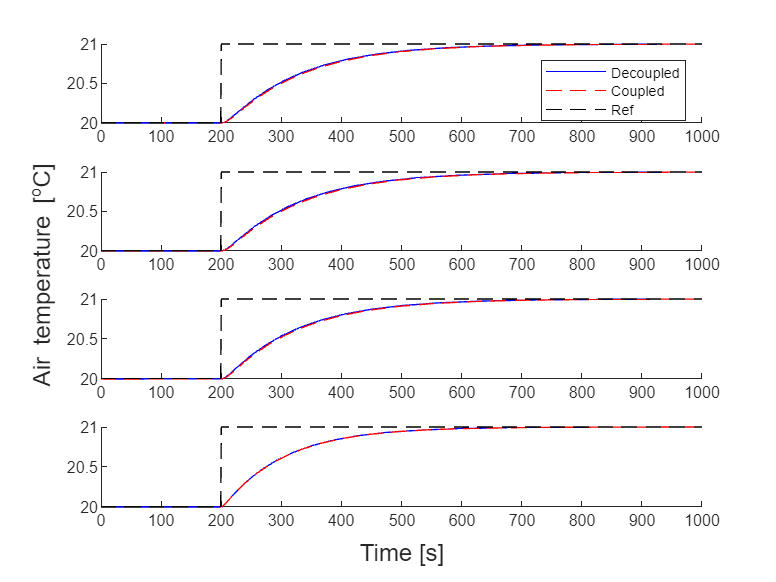

% % % % save('SOF_Performance2.mat','param')
% % % % % % save('SOF_Performance.mat','param')
% load('SOF_Performance.mat')
[resDeSoF,resSOF] = util.SimulateStep(param,"SimulateNonlinearSOFResults",0,1000);

info = stepinfo(resSOF.Ta(:,1),resSOF.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SOF is: %f \n', (info.SettlingTime - 200));

Settling time for SOF is: 607.589600 


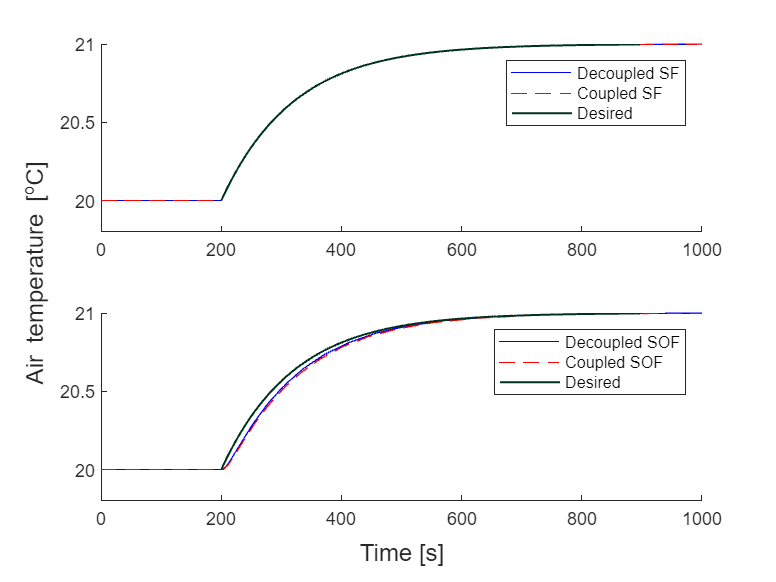


util.CompareDesired(param,'CompareDesired',resDeSF,resSF,resDeSoF,resSOF);

# Synthesize a controller with a setteling time of 2 min. 

### Initizilation

clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);
%Wref
%lowpass filter wich result in a setling time of 2 min (120 sec) .  
s=tf('s');
wref =eye(4)*(1/(24*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;

%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);

## FWMM on SF

param.model.Dwz = 20*eye(4);
param = control.DesignProcedureFWMM(param,0);

Evaluation of design procedure for FWMM 
Gamma is found to be: 0.591719 


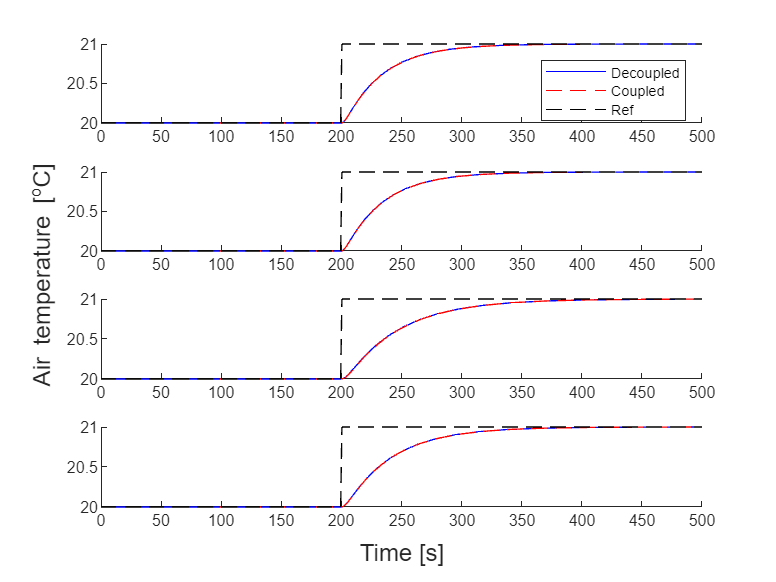

[~,res] = util.SimulateStep(param,"SimulateNonlinearStatefeedbackResults_2_min",0,500);

info = stepinfo(res.Ta(:,1),res.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SF is: %f \n', (info.SettlingTime - 200));

Settling time for SF is: 164.082519 


Attempt with polytopic uncertainties

param = control.DesingProcedureFWMM_Polytopic(param,0,{[-1,1]});

Evaluation of design procedure for FWMM uncertainties
Gamma is found to be: 0.000195 


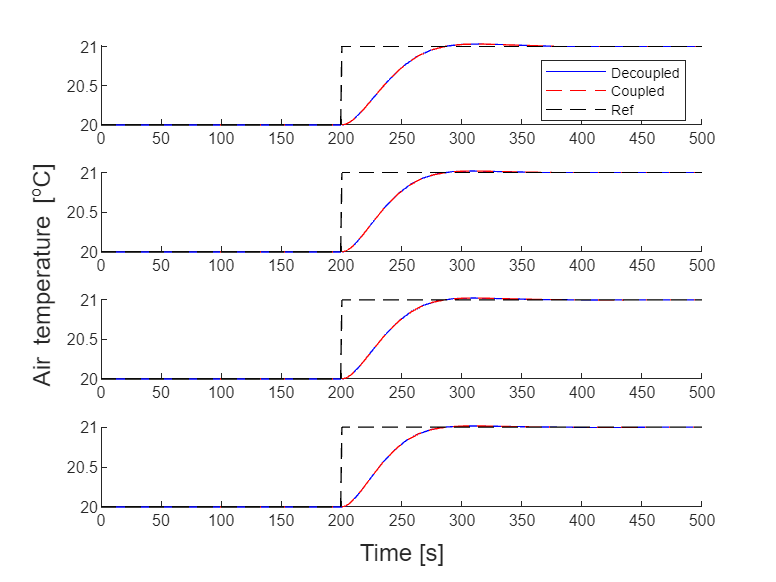

figure()
[~,res] = util.SimulateStep(param,"SimulateNonlinearStatefeedbackResults_2_min",0,500);

info = stepinfo(res.Ta(:,1),res.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SF is: %f \n', (info.SettlingTime - 200));

Settling time for SF is: 169.023594 


## FWMM on SOF

param.model.Dwz = 5*eye(4);
param = control.DesignProcedureSOF_ILMI_FWMM(param,0,{[-1,1]});

ans = 31.3124

ans = 1.2102

ans = 0.4648

ans = 0.2694

ans = 0.2090

ans = 0.1780

ans = 0.1584

ans = 0.1449

ans = 0.1349

ans = 0.1268

ans = 0.1201

ans = 0.1145

ans = 0.1097

ans = 0.1057

ans = 0.1025

ans = 0.0998

ans = 0.0974

ans = 0.0951

ans = 0.0929

ans = 0.0907

ans = 0.0886

ans = 0.0864

ans = 0.0843

ans = 0.0821

ans = 0.0798

ans = 0.0774

ans = 0.0750

ans = 0.0723

ans = 0.0694

ans = 0.0661

ans = 0.0625

ans = 0.0584

ans = 0.0539

ans = 0.0491

ans = 0.0441

ans = 0.0390

ans = 0.0343

ans = 0.0306

ans = 0.0277

ans = 0.0246

ans = 0.0215

ans = 0.0188

ans = 0.0165

ans = 0.0144

ans = 0.0124

ans = 0.0102

ans = 0.0082

ans = 0.0064

ans = 0.0047

ans = NaN

Alpha became NaN after 50 itr. Last value was 0.004707 


ans = 0.0050

ans = 0.0030

ans = 0.0010

ans = -9.3079e-04

Elapsed time is 117.771845 seconds.
Took 53 iterations 
Evaluation of design procedure for ILMI SOF 
Gamma is found to be: 1.000000 
Eigenvalues of the decoupled systems are all negative 


ans =   -3.6363 + 0.0000i  -0.3590 + 0.0000i  -0.0417 + 0.0000i  -2.0143 + 0.1708i  -2.0143 - 0.1708i  -0.0468 + 0.0000i  -3.3639 + 0.0000i  -0.6391 + 0.0000i  -0.0340 + 0.0000i  -3.6961 + 0.0000i  -0.2991 + 0.0000i  -0.0416 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -2.0143 + 2.2733i  -2.0143 - 2.2733i  -3.3094 + 0.0000i  -3.0525 + 0.0000i  -2.0015 + 0.9183i  -2.0015 - 0.9183i  -0.9436 + 0.0000i  -0.6870 + 0.0000i  -0.0339 + 0.0000i  -0.0464 + 0.0000i  -0.0408 + 0.0000i  -0.0409 + 0.0000i


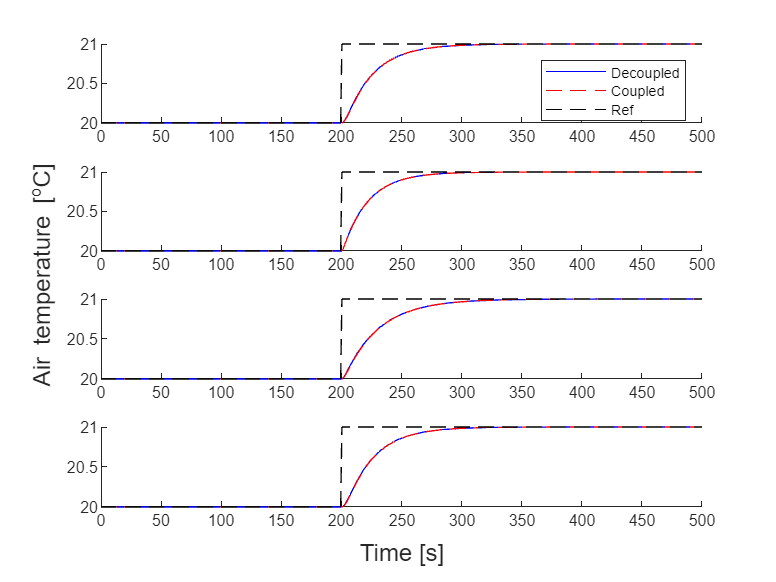

% % % save('SOF_Performance2min.mat','param')
[~,res] = util.SimulateStep(param,"SimulateNonlinearSOFResults_2_min",0,500);

info = stepinfo(res.Ta(:,1),res.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SOF is: %f \n', (info.SettlingTime - 200));

Settling time for SOF is: 120.836759 
